clear all;

pavia = load('PaviaU.mat');

pavia_data = pavia.paviaU;

disp(pavia_data);


(:,:,1) =

         647         604         621         637         625         920         174         414         479        1117         378         675         731         699         579         212         826         865         869         426         994         963         464         547         831         941         655         540        1072         528        1125         427         534         842         369         397         906         479         577         934         541         857        1119         902        1126         422        1085        1250         941         446           0         518         818         836         628         839         558         810         546         552         589         583         830         487         477         801        1233         919        1468         832         566         428         613        1067         682         821        1097        1586        1514        1224        1092         900    

wavelengths = linspace(0.5, 2.3, 103);

cube = hypercube(pavia_data, wavelengths);

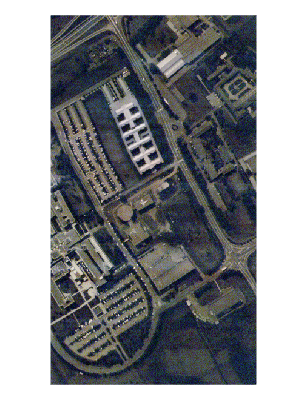

rgb_Image = colorize(cube, "Method","rgb","ContrastStretching",true);
imshow(rgb_Image);

% Reshape 3d matrix to 2d
[m,n,p] = size(pavia_data);

new_2D_matrix = reshape(pavia_data, m, n*p);

disp(new_2D_matrix);

  Columns 1 through 2 730

         647         604         621         637         625         920         174         414         479        1117         378         675         731         699         579         212         826         865         869         426         994         963         464         547         831         941         655         540        1072         528        1125         427         534         842         369         397         906         479         577         934         541         857        1119         902        1126         422        1085        1250         941         446           0         518         818         836         628         839         558         810         546         552         589         583         830         487         477         801        1233         919        1468         832         566         428         613        1067         682         821        1097        1586        1514        1224        1092 